# Lecture 08: In-class Exercises

Images (Image Processing Toolbox sample images, not uploaded): `cameraman.tif`, `pout.tif` and `coins.png`.

One section per exercise: code, outputs and a short answer to the "Think about" questions. Answers that depend on measured numbers are printed by the code as lines starting with `Answer:`. Figures use at most three panels per row so that they stay readable inline in the Live Script and in the PDF export.

clear; close all; clc;
fprintf('MATLAB %s\n', version);

MATLAB 26.2.0.3433840 (R2026b) Update 1


## Exercise 1: pixels and quantization

Load `cameraman.tif`, quantize it to 4, 2 and 1 bit, and downsample it by 8 with and without `imresize`.

I = imread('cameraman.tif');
fprintf('cameraman.tif: %d x %d pixels, class %s\n', size(I, 1), size(I, 2), class(I));

cameraman.tif: 256 x 256 pixels, class uint8


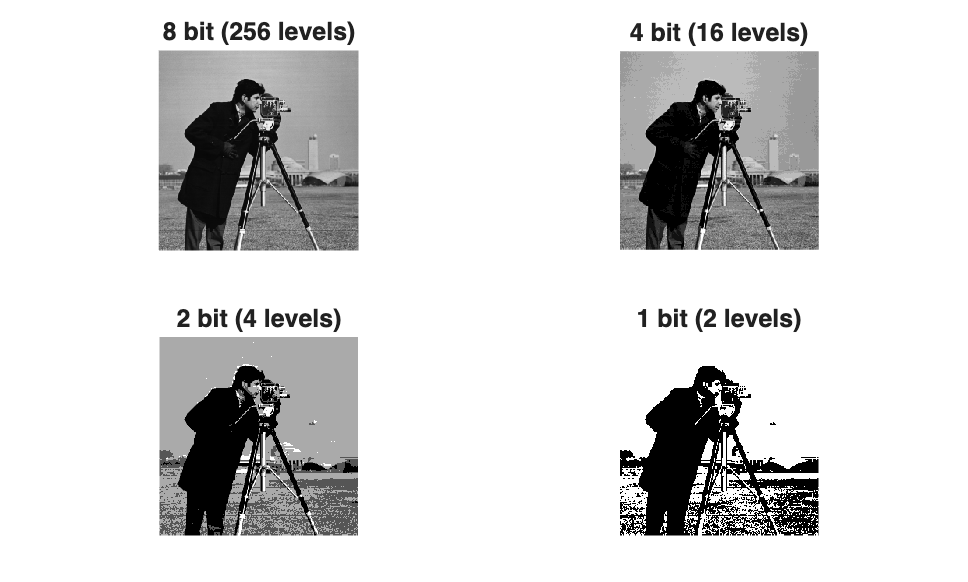


% n-bit quantization: map 0..255 to L = 2^n levels, then back to 0..255
% for display.
bits = [8 4 2 1];
fig = figure; theme(fig, 'light');
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for b = bits
    L = 2^b;
    Iq = uint8(floor(double(I) / (256 / L)) * (255 / (L - 1)));
    nexttile;
    imshow(Iq);
    title(sprintf('%d bit (%d levels)', b, L));
end


% Downsampling by 8: plain decimation keeps every 8th pixel with no
% low-pass filter; imresize uses bicubic interpolation with antialiasing.
Idec = I(1:8:end, 1:8:end);
Ires = imresize(I, 1/8);
fprintf('Downsampled size: %d x %d\n', size(Idec, 1), size(Idec, 2));

Downsampled size: 32 x 32


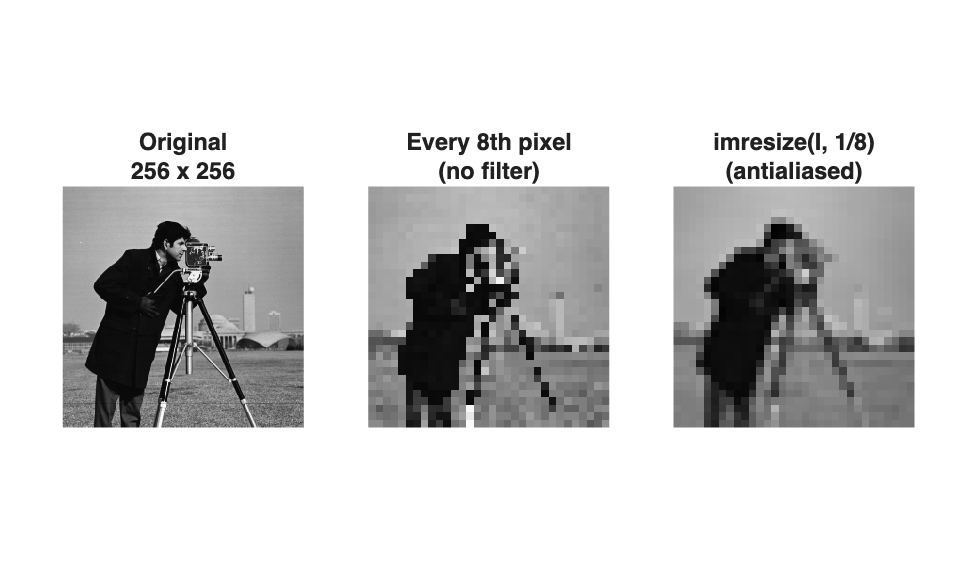


fig = figure; theme(fig, 'light');
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile; imshow(I); title(sprintf('Original\n256 x 256'));
nexttile; imshow(imresize(Idec, 8, 'nearest')); title(sprintf('Every 8th pixel\n(no filter)'));
nexttile; imshow(imresize(Ires, 8, 'nearest')); title(sprintf('imresize(I, 1/8)\n(antialiased)'));

**Answer.** At 4 bits the image looks almost normal apart from slight false contours (bands) in the smooth sky. At 2 bits the cameraman is still clearly recognisable, but the face and the coat lose their shading. At 1 bit only a black-and-white silhouette remains, so I stop recognising details (face, camera, background buildings) at 1 bit.

Aliasing is visible in the plain decimation without a filter: the thin tripod legs break into disconnected pixels, and the fine grass texture turns into a coarse random pattern. The `imresize` result is smoother, because its low-pass filter removes those fine details before sampling.

## Exercise 2: degrade an image

Gaussian noise (variance 0.01), salt & pepper noise (density 0.05), motion blur `fspecial('motion', 15, 30)` and a multiplicative brightness ramp.

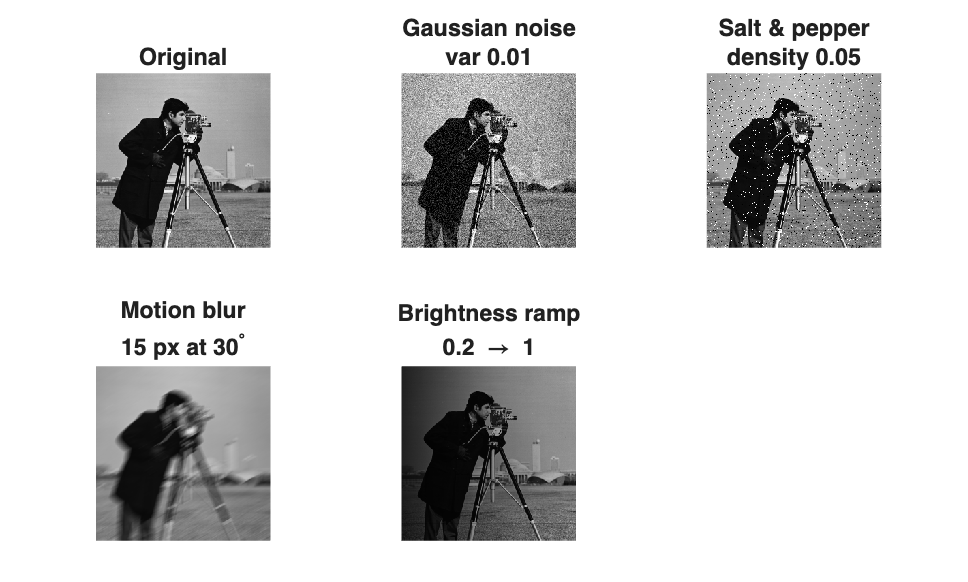

rng(42);
Ig  = imnoise(I, 'gaussian', 0, 0.01);
Isp = imnoise(I, 'salt & pepper', 0.05);

hMotion = fspecial('motion', 15, 30);
Iblur = imfilter(I, hMotion, 'replicate');

% Brightness ramp: gain 0.2 on the left edge rising linearly to 1 on the right.
ramp = repmat(linspace(0.2, 1, size(I, 2)), size(I, 1), 1);
Iramp = im2uint8(im2double(I) .* ramp);

fig = figure; theme(fig, 'light');
tiledlayout(2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile; imshow(I); title('Original');
nexttile; imshow(Ig); title(sprintf('Gaussian noise\nvar 0.01'));
nexttile; imshow(Isp); title(sprintf('Salt & pepper\ndensity 0.05'));
nexttile; imshow(Iblur); title(sprintf('Motion blur\n15 px at 30^\\circ'));
nexttile; imshow(Iramp); title(sprintf('Brightness ramp\n0.2 \\rightarrow 1'));

**Answer.** Gaussian noise is additive: a random value is added to every pixel (`I + n`). The brightness ramp is multiplicative: every pixel is scaled by a gain that depends on its position (`I .* ramp`), like uneven illumination. Salt & pepper noise is neither: it replaces 5 % of the pixels by 0 or 255. Motion blur is a convolution with the 15-pixel line kernel. The median filter fixes the salt & pepper noise, because each impulse is an outlier in its neighbourhood and the median ignores it.

## Exercise 3: contrast and geometry

Histogram of `pout.tif`, then `imadjust`, gamma 0.5, gamma 2 and `histeq`. Finally a 40 x 40 patch enlarged 8 times with nearest and bicubic interpolation.

P = imread('pout.tif');
fprintf('pout.tif: %d x %d pixels, class %s, grey levels used: %d to %d\n', ...
    size(P, 1), size(P, 2), class(P), min(P(:)), max(P(:)));

pout.tif: 291 x 240 pixels, class uint8, grey levels used: 74 to 224


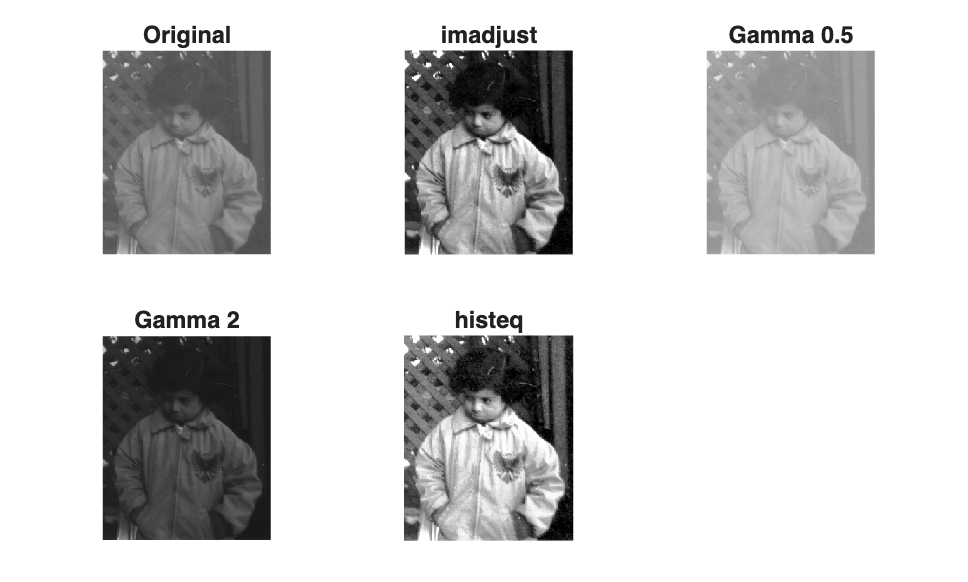


Padj = imadjust(P);                 % stretch, saturating 1 % at each end
Pg05 = imadjust(P, [], [], 0.5);    % gamma 0.5 over the full range
Pg2  = imadjust(P, [], [], 2);      % gamma 2 over the full range
Peq  = histeq(P);

contrastImages = {P, Padj, Pg05, Pg2, Peq};
contrastNames  = {'Original', 'imadjust', 'Gamma 0.5', 'Gamma 2', 'histeq'};

fig = figure; theme(fig, 'light');
tiledlayout(2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
for k = 1:numel(contrastImages)
    nexttile;
    imshow(contrastImages{k});
    title(contrastNames{k});
end

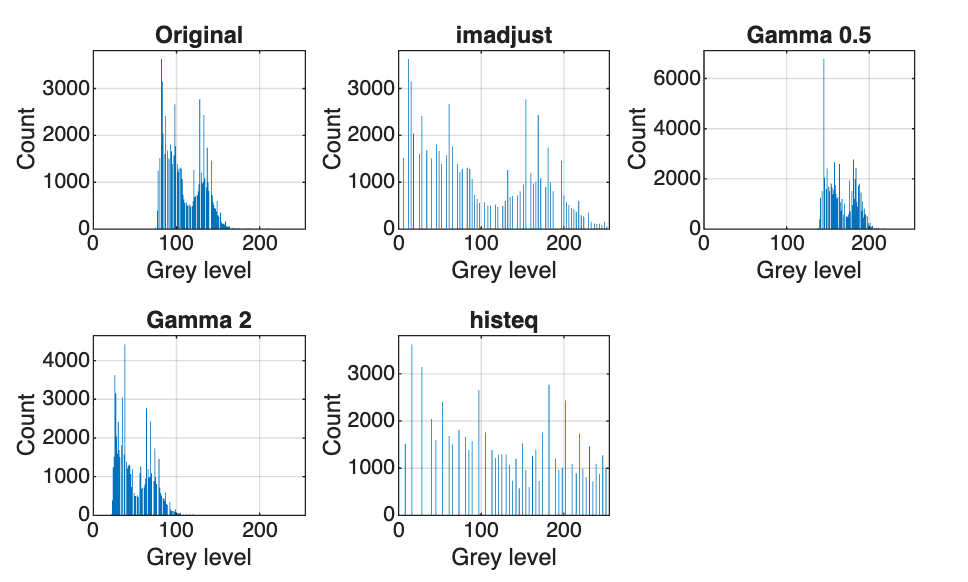


fig = figure; theme(fig, 'light');
tiledlayout(2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
for k = 1:numel(contrastImages)
    nexttile;
    [counts, levels] = imhist(contrastImages{k});
    bar(levels, counts, 1, 'FaceColor', [0 0.4470 0.7410], 'EdgeColor', 'none');
    xlim([0 255]); ylim([0 max(counts) * 1.05]);
    xlabel('Grey level'); ylabel('Count');
    title(contrastNames{k});
    grid on;
end

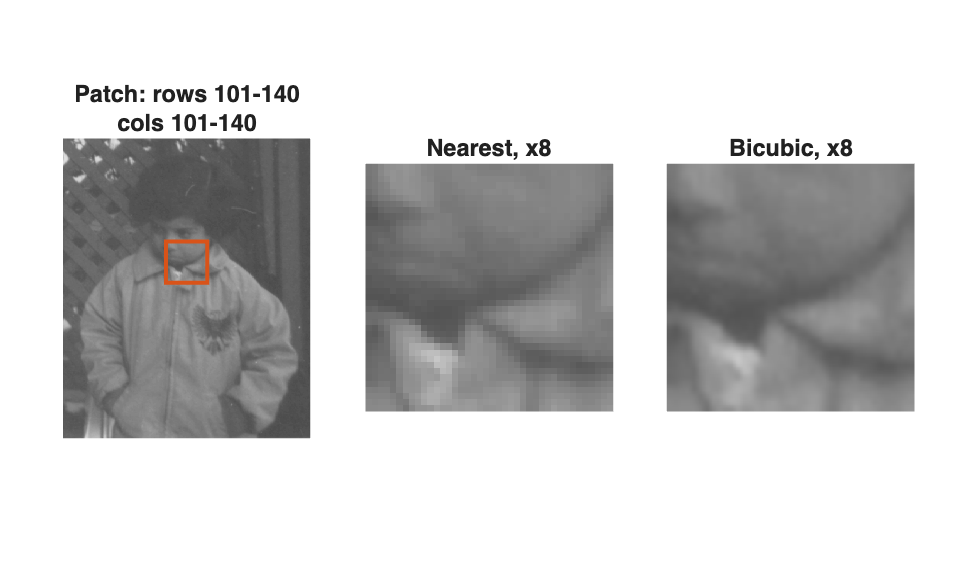


% 40 x 40 patch from the centre of pout.tif, enlarged 8 times.
patchRows = 101:140;
patchCols = 101:140;
patch = P(patchRows, patchCols);

fig = figure; theme(fig, 'light');
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile;
imshow(P);
rectangle('Position', [patchCols(1) - 0.5, patchRows(1) - 0.5, 40, 40], ...
    'EdgeColor', [0.8500 0.3250 0.0980], 'LineWidth', 1.5);
title(sprintf('Patch: rows %d-%d\ncols %d-%d', ...
    patchRows(1), patchRows(end), patchCols(1), patchCols(end)));
nexttile; imshow(imresize(patch, 8, 'nearest')); title('Nearest, x8');
nexttile; imshow(imresize(patch, 8, 'bicubic')); title('Bicubic, x8');

**Answer.** The original uses only a narrow band of grey levels, so it looks flat. `imadjust` looks best to me: it stretches that band over the full range and keeps the tones natural. `histeq` gives the strongest contrast but exaggerates the background and looks harsh.

Gamma below 1 brightens because the grey levels are scaled to [0, 1] and $x^{0.5} > x$ for every $0 < x < 1$. Dark values are lifted the most, while black (0) and white (1) stay fixed.

Nearest copies each pixel into an 8 x 8 block, so the patch looks blocky. Bicubic computes new values from a weighted 4 x 4 neighbourhood, so it creates smooth transitions between the original pixels, at the cost of a slightly softer image.

## Exercise 4: filter and compare

Mean 3 x 3, Gaussian (sigma 1) and median 3 x 3 filters on both noisy images from Exercise 2, PSNR against the original, and the spectrum of the original and the motion-blurred image.

noisyImages = {Ig, Isp};
noiseNames  = {'Gaussian noise', 'Salt & pepper'};
filterNames = {'Mean 3x3', 'Gaussian sigma 1', 'Median 3x3'};

filtered = cell(numel(filterNames), numel(noisyImages));
psnrDb = zeros(numel(filterNames) + 1, numel(noisyImages));
for j = 1:numel(noisyImages)
    N = noisyImages{j};
    filtered{1, j} = imfilter(N, fspecial('average', 3), 'replicate');
    filtered{2, j} = imgaussfilt(N, 1);
    filtered{3, j} = medfilt2(N, [3 3], 'symmetric');
    psnrDb(1, j) = psnr(N, I);
    for k = 1:numel(filterNames)
        psnrDb(k + 1, j) = psnr(filtered{k, j}, I);
    end
end

psnrTable = table(round(psnrDb(:, 1), 2), round(psnrDb(:, 2), 2), ...
    'VariableNames', {'GaussianNoise_PSNR_dB', 'SaltPepper_PSNR_dB'}, ...
    'RowNames', [{'No filter'}, filterNames]);
disp(psnrTable);

                        GaussianNoise_PSNR_dB    SaltPepper_PSNR_dB
                        _____________________    __________________

    No filter                   20.38                  18.21       
    Mean 3x3                    24.35                  23.54       
    Gaussian sigma 1            24.78                  24.05       
    Median 3x3                  24.23                  26.89       




for j = 1:numel(noisyImages)
    [~, best] = max(psnrDb(2:end, j));
    fprintf('Answer: best filter for %s: %s (%.2f dB, %+.2f dB over the noisy image)\n', ...
        noiseNames{j}, filterNames{best}, psnrDb(best + 1, j), psnrDb(best + 1, j) - psnrDb(1, j));
end

Answer: best filter for Gaussian noise: Gaussian sigma 1 (24.78 dB, +4.40 dB over the noisy image)
Answer: best filter for Salt & pepper: Median 3x3 (26.89 dB, +8.67 dB over the noisy image)


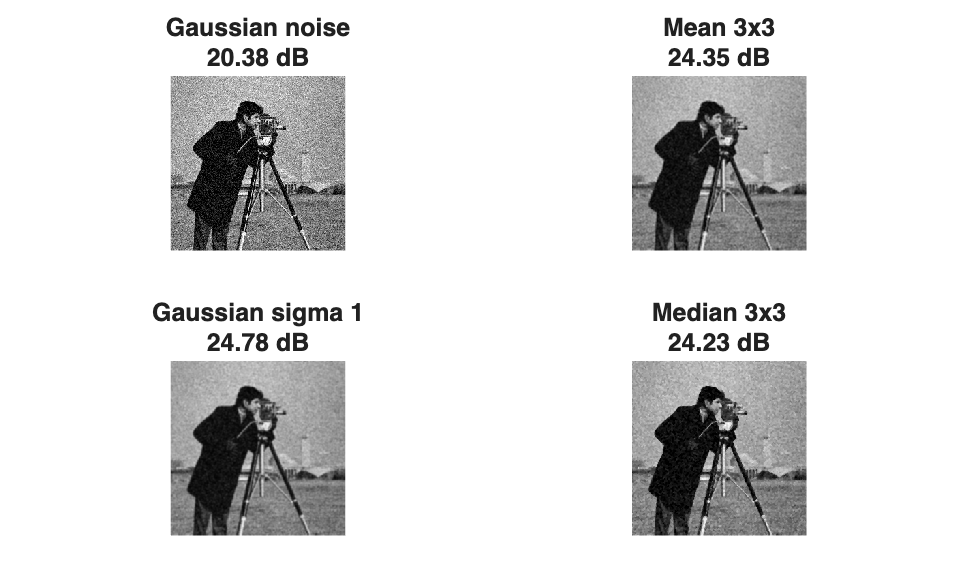

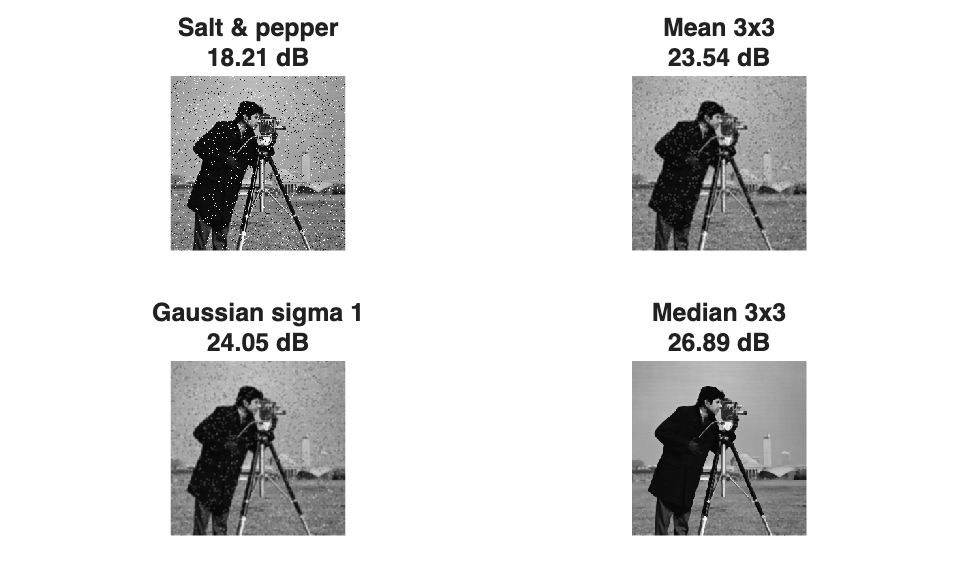


for j = 1:numel(noisyImages)
    fig = figure; theme(fig, 'light');
    tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    nexttile;
    imshow(noisyImages{j});
    title(sprintf('%s\n%.2f dB', noiseNames{j}, psnrDb(1, j)));
    for k = 1:numel(filterNames)
        nexttile;
        imshow(filtered{k, j});
        title(sprintf('%s\n%.2f dB', filterNames{k}, psnrDb(k + 1, j)));
    end
end

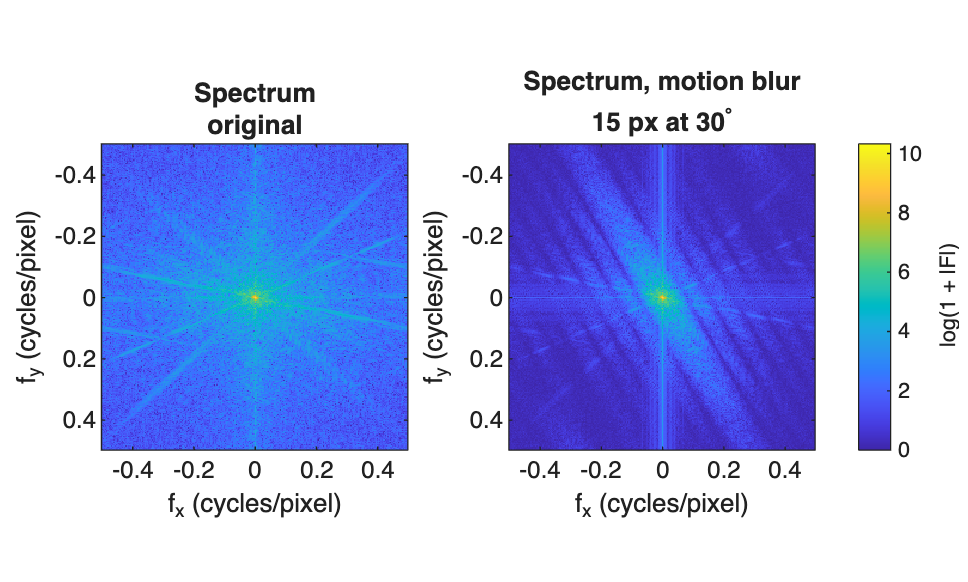


% Spectrum: log magnitude of the centred 2-D DFT.
F0 = fftshift(fft2(im2double(I)));
Fb = fftshift(fft2(im2double(Iblur)));
freq = (-size(I, 1) / 2:size(I, 1) / 2 - 1) / size(I, 1);   % cycles/pixel
logF0 = log(1 + abs(F0));
logFb = log(1 + abs(Fb));
cRange = [0 max(logF0(:))];

fig = figure; theme(fig, 'light');
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile;
imagesc(freq, freq, logF0, cRange); axis image; colormap(gca, parula);
title(sprintf('Spectrum\noriginal'));
xlabel('f_x (cycles/pixel)'); ylabel('f_y (cycles/pixel)');
nexttile;
imagesc(freq, freq, logFb, cRange); axis image; colormap(gca, parula);
title(sprintf('Spectrum, motion blur\n15 px at 30^\\circ'));
xlabel('f_x (cycles/pixel)'); ylabel('f_y (cycles/pixel)');
cb = colorbar;
cb.Layout.Tile = 'east';
cb.Label.String = 'log(1 + |F|)';


% Share of the spectral energy above 0.25 cycles/pixel (high frequencies).
[fx, fy] = meshgrid(freq, freq);
highBand = hypot(fx, fy) > 0.25;
highShare = @(F) 100 * sum(abs(F(highBand)).^2) / sum(abs(F(:)).^2);
fprintf('Answer: energy above 0.25 cycles/pixel: original %.3f %%, blurred %.3f %%\n', ...
    highShare(F0), highShare(Fb));

Answer: energy above 0.25 cycles/pixel: original 0.783 %, blurred 0.030 %


**Answer.** For Gaussian noise the Gaussian filter wins, but only narrowly: 24.78 dB against 24.35 dB (mean) and 24.23 dB (median). A linear filter averages the random deviations out. For salt & pepper the median wins by a wide margin: 26.89 dB against 24.05 dB for the best linear filter. The mean and Gaussian filters spread each impulse into a grey blob instead of removing it.

Blurring removes high frequencies: the share of energy above 0.25 cycles/pixel drops from 0.783 % to 0.030 %. Motion blur averages along one direction only, so it attenuates the frequencies along the 30-degree blur direction and keeps those perpendicular to it. Its spectrum shows dark parallel lines (zeros of the line kernel) that run perpendicular to the blur direction.

## Exercise 5: edges

Sobel and Canny on `cameraman.tif`, Canny with sigma 1, 2 and 3, and Canny on the Gaussian-noise image from Exercise 2 with and without extra smoothing. All thresholds are the defaults.

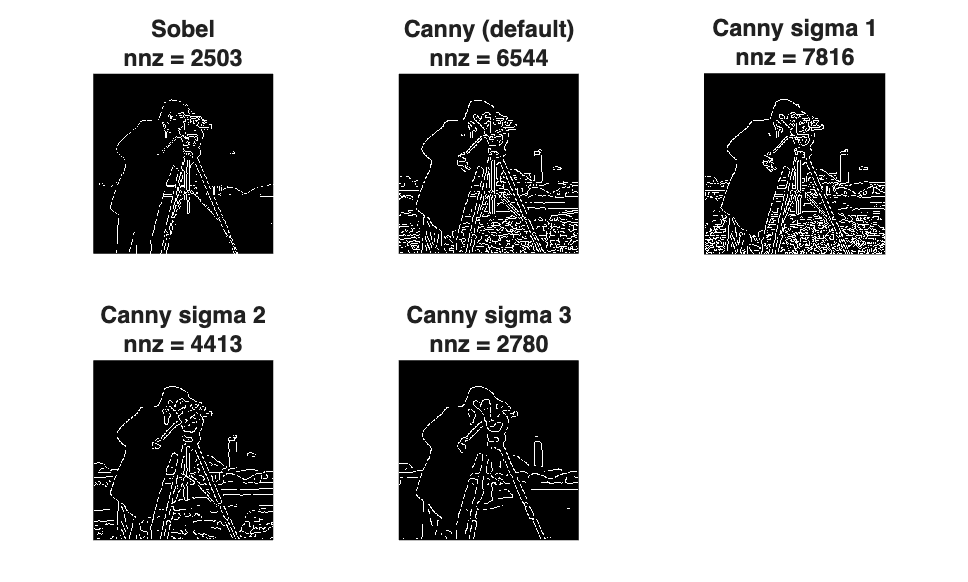

Sobel                  nnz = 2503
Canny (default)        nnz = 6544
Canny sigma 1          nnz = 7816
Canny sigma 2          nnz = 4413
Canny sigma 3          nnz = 2780


Esobel  = edge(I, 'sobel');
Ecanny  = edge(I, 'canny');                 % default sigma sqrt(2)
sigmas  = [1 2 3];
EcSigma = cell(size(sigmas));
for k = 1:numel(sigmas)
    EcSigma{k} = edge(I, 'canny', [], sigmas(k));
end

edgeMaps  = [{Esobel, Ecanny}, EcSigma];
edgeNames = {'Sobel', 'Canny (default)', 'Canny sigma 1', 'Canny sigma 2', 'Canny sigma 3'};
fig = figure; theme(fig, 'light');
tiledlayout(2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
for k = 1:numel(edgeMaps)
    nexttile;
    imshow(edgeMaps{k});
    title(sprintf('%s\nnnz = %d', edgeNames{k}, nnz(edgeMaps{k})));
    fprintf('%-22s nnz = %d\n', edgeNames{k}, nnz(edgeMaps{k}));
end

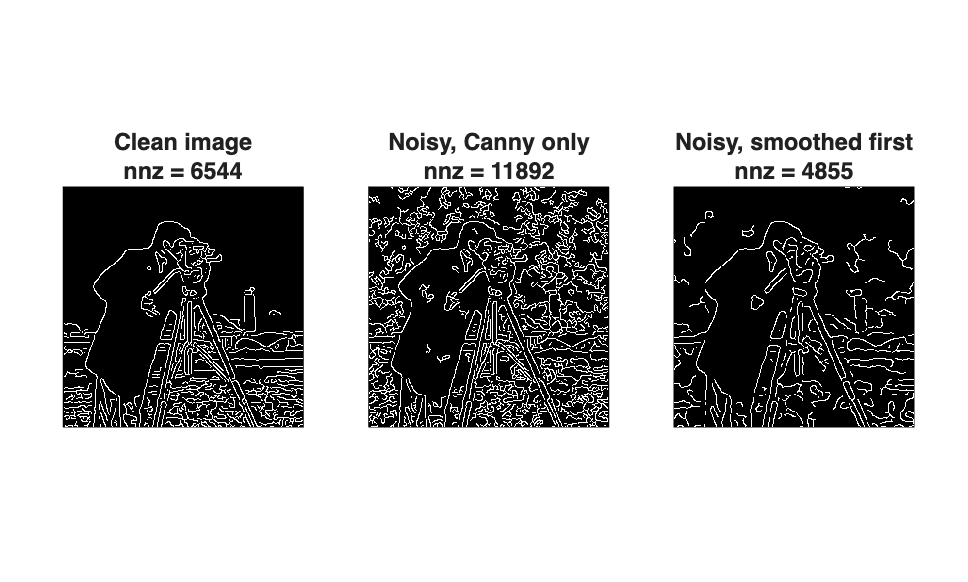


% Noisy image: Canny alone ("without smoothing", only its internal
% sigma sqrt(2)) and Canny after an extra Gaussian smoothing, sigma 2.
EnRaw    = edge(Ig, 'canny');
EnSmooth = edge(imgaussfilt(Ig, 2), 'canny');

fig = figure; theme(fig, 'light');
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile; imshow(Ecanny);   title(sprintf('Clean image\nnnz = %d', nnz(Ecanny)));
nexttile; imshow(EnRaw);    title(sprintf('Noisy, Canny only\nnnz = %d', nnz(EnRaw)));
nexttile; imshow(EnSmooth); title(sprintf('Noisy, smoothed first\nnnz = %d', nnz(EnSmooth)));


removed = nnz(EnRaw) - nnz(EnSmooth);
if removed >= 0
    change = 'removed';
else
    change = 'added';
end
fprintf('Answer: smoothing changes the noisy edge count from %d to %d: %d edge pixels (%.1f %%) %s\n', ...
    nnz(EnRaw), nnz(EnSmooth), abs(removed), 100 * abs(removed) / nnz(EnRaw), change);

Answer: smoothing changes the noisy edge count from 11892 to 4855: 7037 edge pixels (59.2 %) removed


**Answer.** A larger Canny sigma smooths more before the gradient is taken. Fine texture (grass, background buildings) disappears, the remaining edges become longer and smoother, and corners get rounded. The edge-pixel count falls from 7816 (sigma 1) to 4413 (sigma 2) and 2780 (sigma 3). Sigma 1 keeps the most detail but also the most clutter.

On the noisy image, Canny alone marks 11892 edge pixels, almost twice the 6544 of the clean image. The extra edges are short, scattered fragments that come from the noise. Smoothing first removes 7037 of them (59 %), leaving 4855. The edge count alone does not tell which pixels are correct, so the figure is needed to see that the remaining edges follow real outlines.

## Exercise 6: segment and measure

Otsu threshold on `coins.png`, cleaning with `imfill`, `imopen` and `bwareaopen`, then labelling and measuring every coin.

C = imread('coins.png');
level = graythresh(C);
fprintf('coins.png: %d x %d pixels, Otsu level %.3f (grey level %.0f)\n', ...
    size(C, 1), size(C, 2), level, 255 * level);

coins.png: 246 x 300 pixels, Otsu level 0.494 (grey level 126)



% imfill comes before imopen: one dim coin is only a thin ring after Otsu,
% and opening first would break the ring so that it could not be filled.
BW0 = imbinarize(C, level);
BW1 = imfill(BW0, 'holes');             % fills dark holes inside the coins
BW2 = imopen(BW1, strel('disk', 2));    % removes small bright specks and thin spurs
BW3 = bwareaopen(BW2, 50);              % removes objects smaller than 50 pixels

% Objects, holes (objects minus Euler number) and foreground pixels per step.
stages = {BW0, BW1, BW2, BW3};
stageNames = {'Otsu', '+ imfill', '+ imopen', '+ bwareaopen'};
objects = zeros(numel(stages), 1);
holes = zeros(numel(stages), 1);
pixels = zeros(numel(stages), 1);
for k = 1:numel(stages)
    cc = bwconncomp(stages{k});
    objects(k) = cc.NumObjects;
    holes(k) = cc.NumObjects - bweuler(stages{k}, 8);
    pixels(k) = nnz(stages{k});
end
disp(table(objects, holes, pixels, 'RowNames', stageNames, ...
    'VariableNames', {'Objects', 'Holes', 'ForegroundPixels'}));

                    Objects    Holes    ForegroundPixels
                    _______    _____    ________________

    Otsu              15        31           22290      
    + imfill          10         0           23153      
    + imopen          10         0           23151      
    + bwareaopen      10         0           23151      




[Lc, nCoins] = bwlabel(BW3);
stats = regionprops(Lc, 'Area', 'Centroid', 'EquivDiameter');
coinTable = table((1:nCoins)', [stats.Area]', round([stats.EquivDiameter]', 1), ...
    'VariableNames', {'Coin', 'Area_px', 'EquivDiameter_px'});
disp(coinTable);

    Coin    Area_px    EquivDiameter_px
    ____    _______    ________________

      1      2651            58.1      
      2      1852            48.6      
      3      2680            58.4      
      4      1810              48      
      5      2753            59.2      
      6      2510            56.5      
      7      2594            57.5      
      8      2544            56.9      
      9      1893            49.1      
     10      1864            48.7      



[maxArea, largest] = max([stats.Area]);
fprintf('Answer: %d coins labelled. Largest coin: #%d, area %d px.\n', nCoins, largest, maxArea);

Answer: 10 coins labelled. Largest coin: #5, area 2753 px.


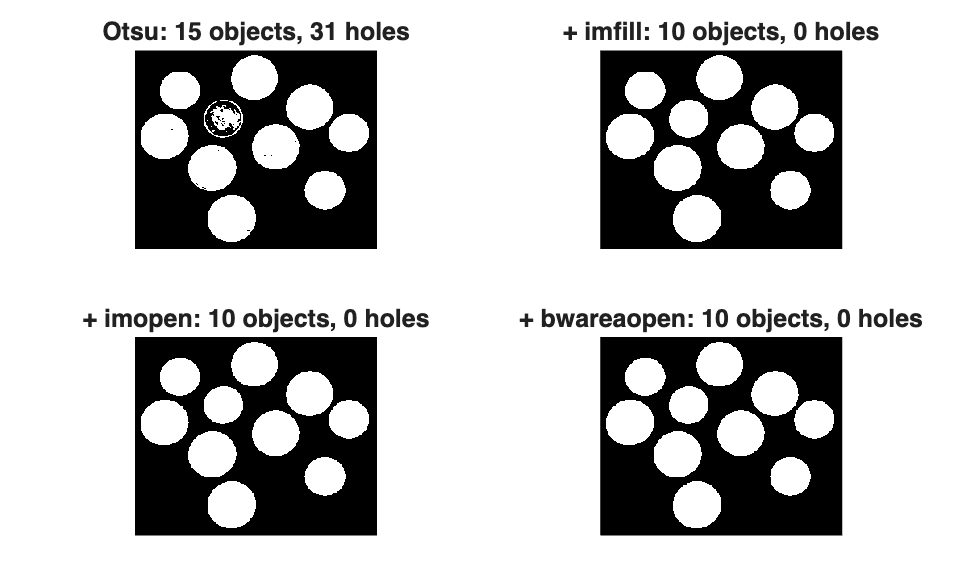


fig = figure; theme(fig, 'light');
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for k = 1:numel(stages)
    nexttile;
    imshow(stages{k});
    title(sprintf('%s: %d objects, %d holes', stageNames{k}, objects(k), holes(k)));
end

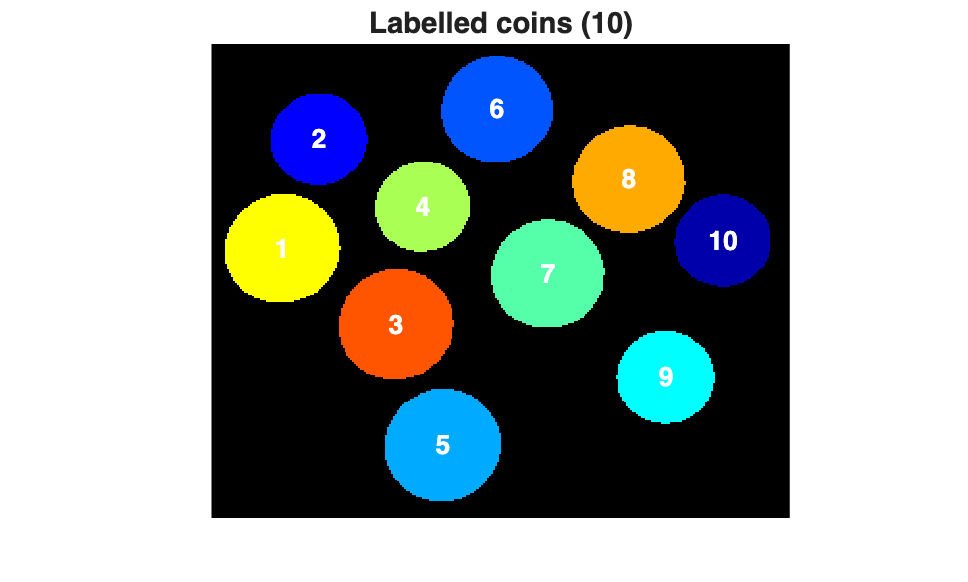


fig = figure; theme(fig, 'light');
imshow(label2rgb(Lc, 'jet', 'k', 'shuffle'));
hold on;
for k = 1:nCoins
    text(stats(k).Centroid(1), stats(k).Centroid(2), sprintf('%d', k), ...
        'Color', 'w', 'FontWeight', 'bold', 'HorizontalAlignment', 'center');
end
hold off;
title(sprintf('Labelled coins (%d)', nCoins));

**Answer.** The table of stages shows what each step changed. The raw Otsu mask has 15 objects and 31 holes: dark details on the coin faces fall below the Otsu level, and one dim coin (#4, upper left) is only a thin ring with 5 small bright specks inside it. `imfill` does almost all the work: it fills all 31 holes, and the specks inside the ring become part of the filled coin, so 15 objects become 10. `imopen` then only smooths the outlines (2 pixels change), and `bwareaopen` finds nothing below 50 pixels left to remove. Here it acts only as a safety net.

The order matters. In a first run with `imopen` before `imfill`, the opening broke the dim coin's ring. The coin could then not be filled and was measured as a 555-pixel fragment instead of a full coin.

The coins form two size groups: four small coins of 1810-1893 pixels (about 48-49 px in diameter) and six large coins of 2510-2753 pixels (about 57-59 px). The largest is coin #5 with 2753 pixels. Touching coins would merge into one label, because `bwlabel` only separates pixels that are not connected. In `coins.png` the coins do not touch, so every coin gets its own label. Touching coins would need a split, for example a distance transform and watershed.